# Robot Navigation Project - Organize Sequence Data

This dataset was obtained from the UCI Machine Learning Repository. 

You can find more information on this dataset here:

[https://archive.ics.uci.edu/ml/datasets/Wall-Following+Robot+Navigation+Data](http://Wall-Following Robot Navigation Data Set)

Load the unprocessed sensor data. This mat file contains 3 variables.

- `label`: The action the robot should take at this time step. At any point, the robot can either move forward, turn slightly to the left, turn slightly to the right, or turn sharply to the right

- `sensor1`: Sensor reading from the front of the robot

- `sensor2`: Sensor reading from the left of the robot

load robotData.mat

## Display data

Display the first feature of the sequence data. You can use the function `displaySequence` located at the bottom of the script. This function takes two inputs, the sensor data and the class labels.

Display the second feature.

## Organize data

The original data source structured the data as follows:

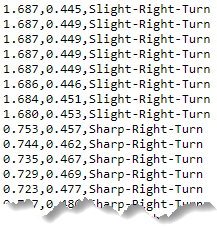

The data was imported into MATLAB with one variable per column. To train a LSTM, the sequence data must be combined into one matrix. 

- The matrix should have two rows (one for each sensor reading)

- The columns are the time steps

The examples used in the course used training data structured as a cell array where each element contained one sequence. For example, in the musical instrument recordings, each sequence was one recording.

In this dataset, there is only one sequence, so you do not need to make a cell array of your data.

## Create matrix of sequence data

Concatenate the two vectors of sensor data into one matrix.

Transpose the matrix so that the columns are the time steps.

## Transpose sequence labels

Each time step of the sequence data has a label. The labels should be stored in a row vector, but currently it is a column. Take the transpose.

You can use the `summary` function to view the class distribution of the data.

## Seperate training and testing data

You can use the end of the sequence to test your network. You can use the last 1000 time steps with the following code (if your sequences and labels are stored in variables `X` and `Y`):

## Train the network

The template script `train_template.mlx` uses a mat file named `robotDataProcessed.mat` to train a long short-term memory network. Ensure your processed data matches the data in this file, and move onto Part 2 of the project.

This function displays the sequence data colored by its corresponding label.

function displaySequence(X,Y)
    figure
    classNames = categories(Y);
    for j = 1:length(classNames)
        label = classNames(j);
        idx = find(Y == label);
        hold on
        plot(idx,X(idx),'*')
    end
    hold off
    legend(classNames,'Location','northwest')
end